# ESA Signals Acoustic Modem Project

#### Elvis Wolcott and Melissa Kazazic

Deliverables:

1. A brief report that includes an introduction, block diagram, equations used, graphs of signals in the time domain, and graphs of signals in the frequency domain.

2. Link to audio recordings if you produced new ones.

3. Your code.

4. Short demo video (2 minutes or less)

Start with hello example.

clear
load('short_modem_rx.mat');

Play and plot initial graphs of signal

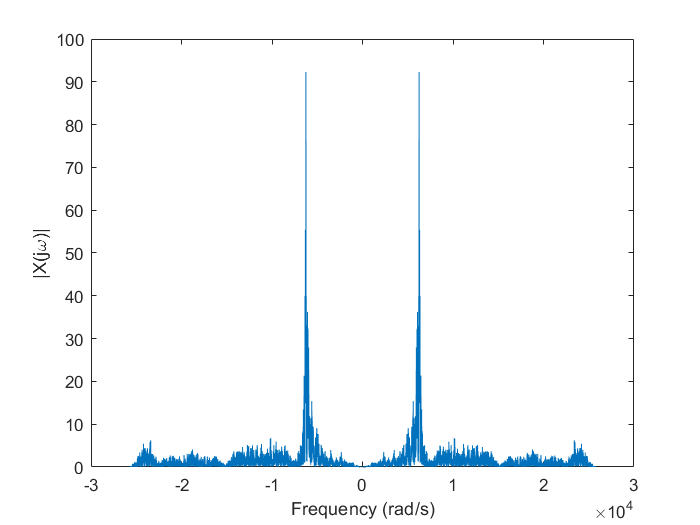

soundsc(y_r,Fs)
plot_ft_rad(y_r,Fs);

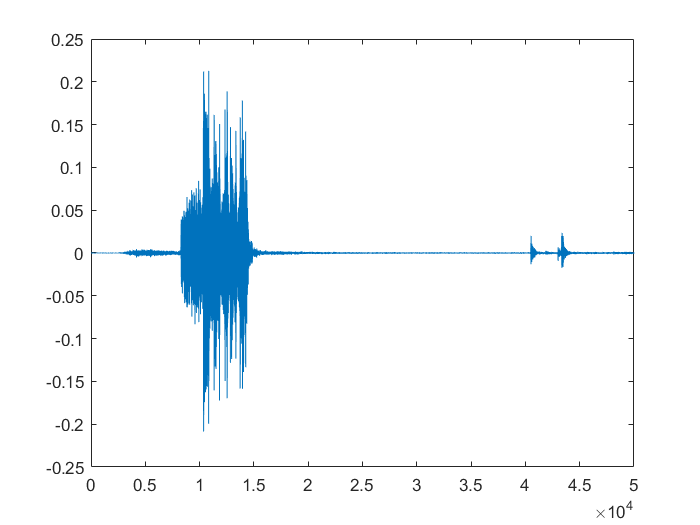

figure()
plot(y_r)

Find the start of the signal

index = find_start_of_signal(y_r,x_sync)

index = 8293

Trim according to start of signal

y_r_crop = y_r(index:end);

Play and plot cropped signal

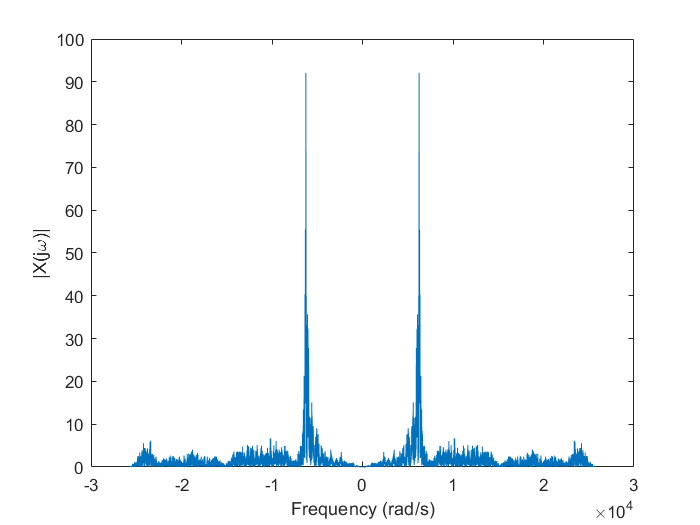

soundsc(y_r_crop,Fs)
plot_ft_rad(y_r_crop,Fs);

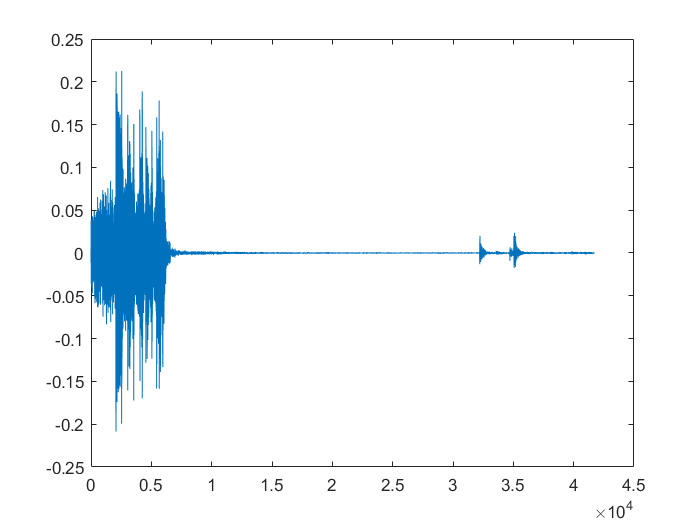

figure()
plot(y_r_crop)

Frequency Shift

t = 1:length(y_r_crop)

t =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


cos_fc = cos(2*pi*f_c*(t/Fs))

cos_fc =     0.7200    0.0368   -0.6670   -0.9973   -0.7691   -0.1102    0.6104    0.9892    0.8140    0.1830   -0.5505   -0.9757   -0.8546   -0.2549    0.4876    0.9569    0.8904    0.3253   -0.4220   -0.9330   -0.9215   -0.3940    0.3542    0.9040    0.9476    0.4605   -0.2844   -0.8701   -0.9685   -0.5246    0.2131    0.8315    0.9842    0.5858   -0.1407   -0.7883   -0.9946   -0.6438    0.0674    0.7410    0.9995    0.6984    0.0061   -0.6895   -0.9991   -0.7491   -0.0797    0.6344    0.9932    0.7958


y_r_crop.*cos_fc